# Multiobjective Problem with Non-Linear Constraint (TNK)

This example shows how to find the Pareto front for a multiobjective problem in the presence of a non-linear constraint using Matlab's gamuliobj algorithm and the Python-based CNSGA or MOBO algorithm within the Xopt module. Start a parallel worker pool before running (e.g. with >> parpool), else gamultiobj function call will start one automatically.

The problem to be solved is the TNK problem: $n=2$ variables: $x_i \in \left\lbrack 0,\pi \right\rbrack ,i=1,2$

Objectives:

- 
$$f_i \left(x\right)=x_i$$


Constraints:

- 
$$g_1 \left(x\right)=-x_1^2 -x_2^2 +1+0\ldotp 1\ldotp \cos \left(16\ldotp \arctan \left(\frac{x_1 }{x_2 }\right)\right)\le 0$$


- 
$$g_2 \left(x\right)={\left(x_1 -1/2\right)}^2 +{\left(x_2 -1/2\right)}^2 \le 0\ldotp 5$$


There are two objective functions and two decision variables `x`. The constraints for gamultiobj are defined in the file TNK_constraints.m, and in TNK_xopt for Xopt.

fitnessfcn = @(x) x;

Find the Pareto front using Matlab.

rng default % For reproducibility
opts=optimoptions('gamultiobj','UseParallel',true);
lb=[0 0]; ub=[pi pi];
[x,fval,~,gaout] = gamultiobj(fitnessfcn,2,[],[],[],[],lb,ub,@TNK_constraints,opts);

Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.


Find the Pareto front using Xopt (using default MOBO algorithm).

X = Xopt("TNK_xopt",2,2) ; % Define Xopt object using fitnessfcn_xopt function with 2 inputs/2 outputs
X.Optimizer = "cnsga" ; % "mobo" or "cnsga" supported
X.verbose=true; % Store output from Xopt run
X.xrange = [0 0;pi pi] ; % allow x to take range [0,pi]
X.yrange = [0 0;pi pi] ; % allow objective functions to take range [0,pi]
X.runopt() ; % run Xopt optimizer
% Get returned points in parameter space
x1 = X.results.variables(1,:) ;
x2 = X.results.variables(2,:) ;
% Get objective function results (pareto front)
y1 = X.results.objectives(1,:) ;
y2 = X.results.objectives(2,:) ;
disp(X.xopt_out) % show output of Xopt run

  _   
                | |  
__  _____  _ __ | |_ 
\ \/ / _ \| '_ \| __|
 >  < (_) | |_) | |_ 
/_/\_\___/| .__/ \__|
          | |        
          |_|        

_________________________________
Parallel execution with 6 workers
Loading as YAML file: xopt_eval.yaml

            Xopt 
________________________________           
Version: 0.4.3+153.g1d11100.dirty
Configured: True
Config as YAML:
xopt: {output_path: /home/glen/xopt/examples/matlab, verbose: true, algorithm: cnsga}
algorithm:
  name: cnsga
  function: xopt.cnsga.cnsga
  options: {max_generations: 400, population_size: 40, crossover_probability: 0.8,
    mutation_probability: 0.2, selection: auto, verbose: true, population: null, seed: null}
simulation:
  name: xopt_eval
  evaluate: xopt_eval.evaluate_func
  options: {matlab_f: xopt_fun, nargout: 2, verbose: true}
vocs:
  name: xopt_eval
  description: null
  simulation: xopt_eval
  templates: null
  variables:
    x1: [0, 3.14159]
    x2: [0, 3.14159]
  objectives: {y1: MI

Plot the constrained solution and the non-linear constraint using both the Matlab and Xopt optimizer outputs.

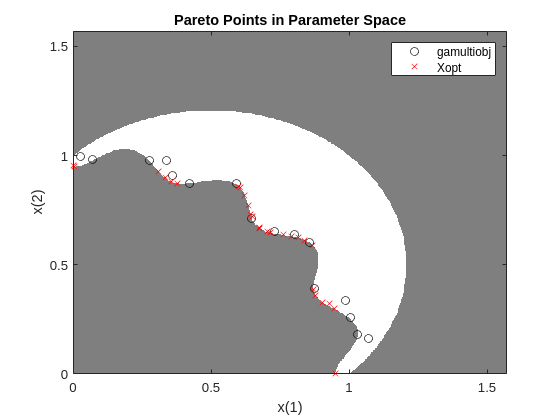

g1 = @(x1,x2) -x1.^2-+ x2.^2 + 1.0 - 0.1 * cos(16 .* atan2(x1, x2)) ;
g2 = @(x1,x2) (x1 - 0.5).^2 + (x2 - 0.5).^2 ;
xv=linspace(0,pi,1000);
[X1,X2]=meshgrid(xv,xv);
c = g1(X1,X2)<=0 & g2(X1,X2)<=0.5;
imagesc(xv,xv,c); colormap([0.5 0.5 0.5;1 1 1]); set(gca,'YDir','normal');
hold on
plot(x(:,1),x(:,2),'ko',x1,x2,'rx')
hold off
axis([0 pi/2 0 pi/2]);
xlabel('x(1)')
ylabel('x(2)')
title('Pareto Points in Parameter Space')
legend({'gamultiobj' 'Xopt'})